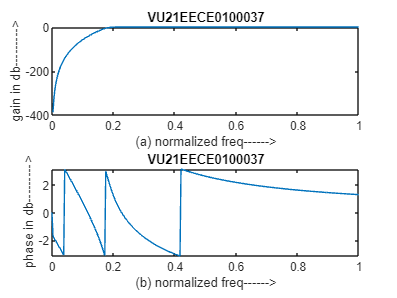

%Butterworth High Pass Filter
clc;
close all;
clear all;
format long;
rp=input('enter the passband ripple:(default:0.2)');
rs=input('enter the stopband ripple:(default:40)');
wp=input('enter the passband frequency:(default:2000)');
ws=input('enter the stopband frequency:(default:3500)');
fs=input('enter the sampling frequency:(default:8000)');
w1=2*wp/fs;
w2=2*ws/fs;
[n,wn]=buttord(w1,w2,rp,rs,'s');
[z,p,k]= butter(n,wn);
[b,a]=butter(n,wn,'high','s');
w=0:0.01:pi;
[h,om]=freqs(b,a,w);
m=20*log10(abs(h));
an=angle(h);
subplot(2,1,1);
plot(om/pi,m);
ylabel('gain in db--------->');
xlabel('(a) normalized freq------>');
title('VU21EECE0100037');
subplot(2,1,2);
plot(om/pi,an);
ylabel('phase in db--------->');
xlabel('(b) normalized freq------>');
title('VU21EECE0100037');